close all; clear;
d = 2;
k = 3;
n = 5000;

## Generate data

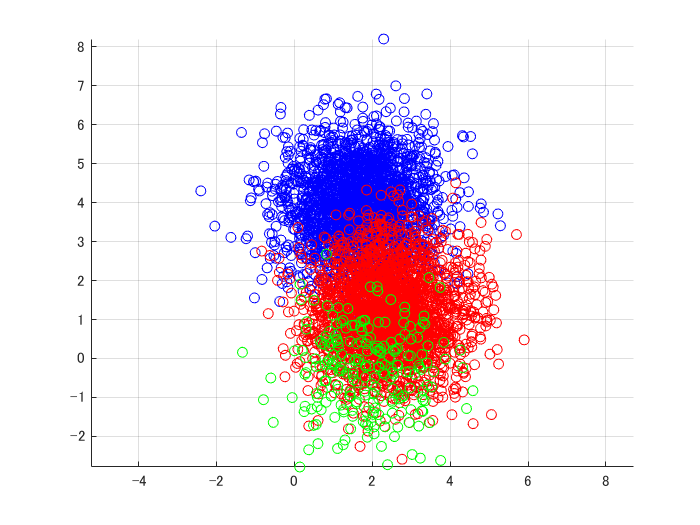

[X,label] = kmeansRnd(d,k,n);
plotClass(X,label);

## kmeans with random initialization

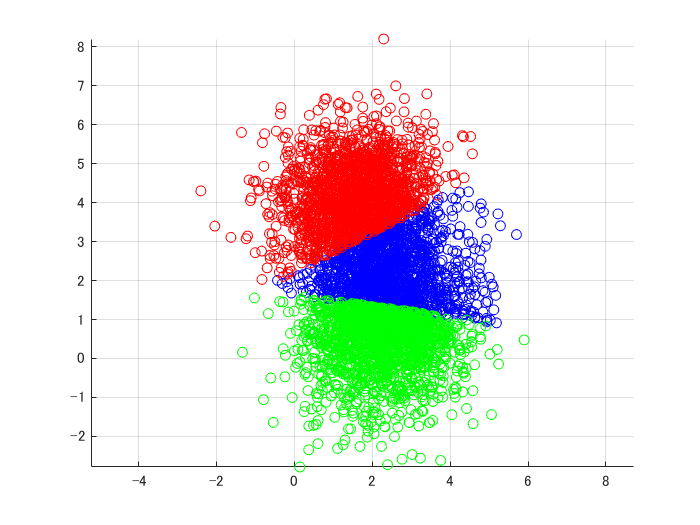

y = kmeans(X,k);
figure;
plotClass(X,y);

## kmeans init with labels

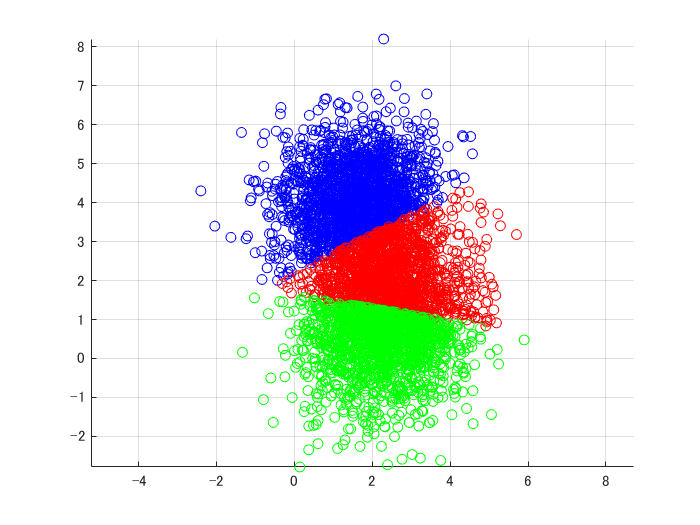

y = kmeans(X,label);
figure;
plotClass(X,y);

## kmeans init with centers

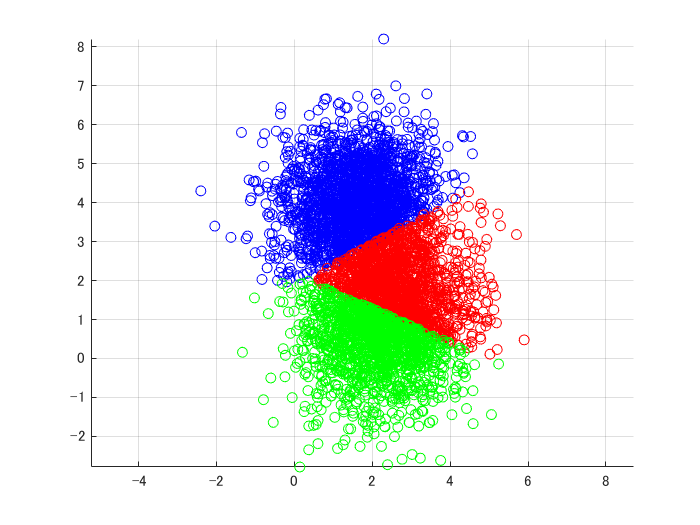

mu = rand(d,k);
y = kmeans(X,mu);
figure;
plotClass(X,y);

## kmeans init with kmeans++ seeding

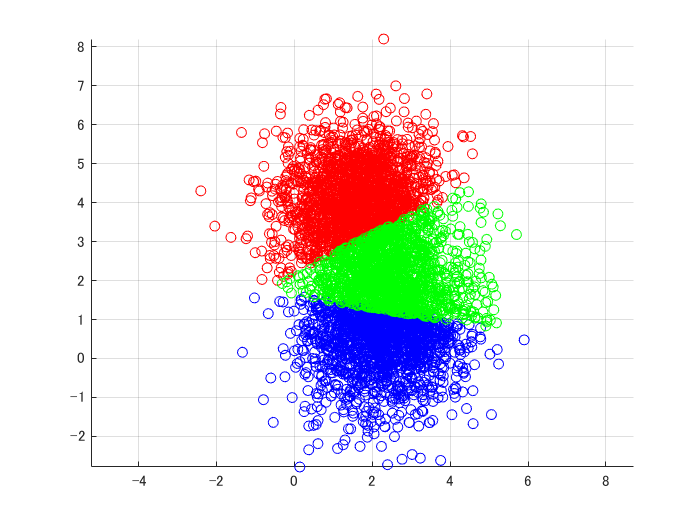

y = kmeans(X,kseeds(X,k));
figure;
plotClass(X,y);

## kmeans++ seeding

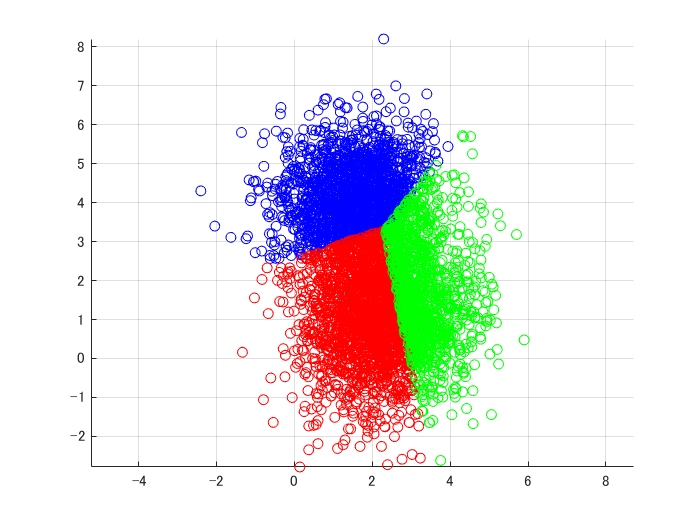

mu = kseeds(X,k);
[~,y] = min(dot(mu,mu,1)'/2-mu'*X,[],1); % assign sample labels
figure;
plotClass(X,y);